# **Simulate the Simulink-based Ramsey-Cass-Koopmans Model using Parallel Computing**

This example shows how to simulate the Simulink version of the Ramsey-Cass-Koopmans model using parallel computing constructs to speed up the simulation process.

*Copyright 2016-2025 The MathWorks, Inc.*

## Create lattices of $(k, c)$ points for the simulation.

nPoints = 20; % Adjust this parameter to increase/decrease the number of simulations
k0Vec = linspace(0, 100, nPoints);
c0Vec = linspace(0, 3, nPoints);
[K0, C0] = meshgrid(k0Vec, c0Vec);

## Set up an array of simulation input objects representing the different initial conditions for the model.

For each $(k_0, c_0)$ pair, set up a simulation object that sets the initial value for per-capita wealth to $k_0$ and for per-capita consumption to $c_0$. 

We also use the stiff system solver [`ode15s`](matlab: doc ode15s) and a stop time of 45 time units.

mdl = "RCK_Model";
nTrials = numel(K0);
in(nTrials, 1) = Simulink.SimulationInput(mdl);
for idx = 1:nTrials
    in(idx) = Simulink.SimulationInput(mdl);
    in(idx) = setBlockParameter(in(idx), mdl + "/capital", ...
        "InitialCondition", num2str(K0(idx)));
    in(idx) = setBlockParameter(in(idx), mdl + "/consumption", ...
        "InitialCondition", num2str(C0(idx)));
    in(idx) = setModelParameter(in(idx), ...
        "StopTime", "45", "Solver", "ode15s");
end % for

## Perform the simulations in parallel.

This approach uses the `parsim` function to automatically run the different simulations, starting from different initial values $(k_0, c_0)$, in parallel.

out = parsim(in, "ShowProgress", "on");

[23-Jan-2023 18:19:14] Checking for availability of parallel pool...
[23-Jan-2023 18:19:14] Starting Simulink on parallel workers...
[23-Jan-2023 18:19:15] Loading project on parallel workers...
[23-Jan-2023 18:19:15] Configuring simulation cache folder on parallel workers...
[23-Jan-2023 18:19:16] Loading model on parallel workers...
[23-Jan-2023 18:19:21] Running simulations...
[23-Jan-2023 18:19:23] Completed 1 of 400 simulation runs
[23-Jan-2023 18:19:23] Completed 2 of 400 simulation runs
[23-Jan-2023 18:19:23] Completed 3 of 400 simulation runs
[23-Jan-2023 18:19:24] Completed 4 of 400 simulation runs
[23-Jan-2023 18:19:24] Completed 5 of 400 simulation runs
[23-Jan-2023 18:19:24] Completed 6 of 400 simulation runs
[23-Jan-2023 18:19:24] Completed 7 of 400 simulation runs
[23-Jan-2023 18:19:24] Completed 8 of 400 simulation runs
[23-Jan-2023 18:19:24] Completed 9 of 400 simulation runs
[23-Jan-2023 18:19:24] Completed 10 of 400 simulation runs
[23-Jan-2023 18:19:24] Completed 11 

## Plot the results.

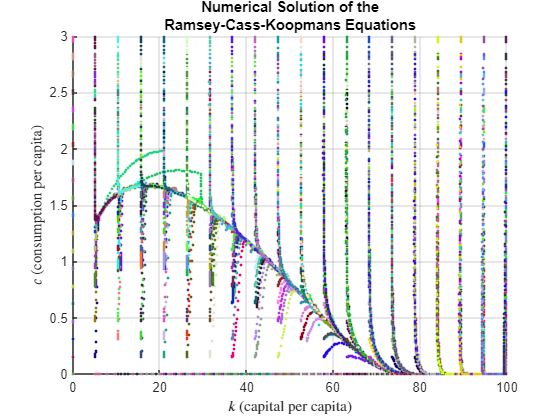

figure
hold on
for idx = 1:length(out)
    simOut = out(idx);
    yout = get(simOut, "yout");
    if ~isempty(yout)
        plot(yout(:,1), yout(:,2), ".", "Color", rand(1, 3))
    end % if
end % for
axis([0, 100, 0, 3])
xlabel("$k$ (capital per capita)", "Interpreter", "latex")
ylabel("$c$ (consumption per capita)", "Interpreter", "latex")
title(sprintf("Numerical Solution of the\nRamsey-Cass-Koopmans Equations"))
grid on